Rubén Vera Martínez, NIA: 241456

Sara Soriano Rossa, NIA: 240007

**PROBLEM 1**

**a) State the null and alternative hypotheses for the research question indicated above.**

Hipótesis:


$$\begin{array}{l}
H_0 :\mu_1 =\mu_2 =\ldotp \ldotp \ldotp =\mu_k \Rightarrow \delta =0\\
H_A :\mu_l \not= \mu_2 \;\textrm{for}\;\textrm{at}\;\textrm{least}\;\textrm{two}\;l\not= l^{\prime } 
\end{array}$$


donde $\mu$ es la media de la población y k el número de grupos relacionados. En este caso k = 11.

**b) Reduce the dimensionality of your input data by projecting it linearly into a unique dimension with maximum variance. Assess whether, under this new representation, we may analyze whether there are significant differences between the images from the 11 conditions with methods that require gaussianity. Clearly indicate your conclusion.**

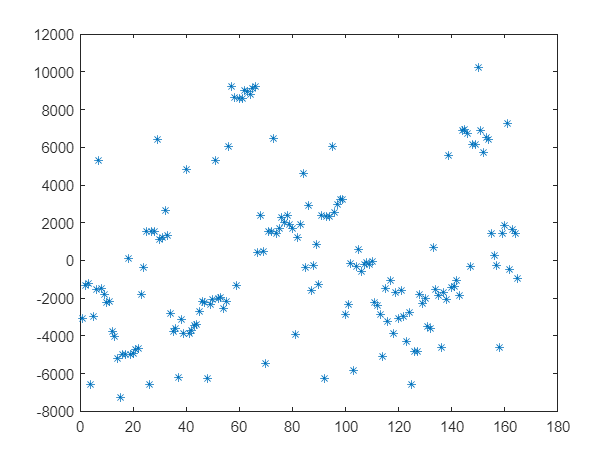

loaded = load('SM22_Lab_6_FaceImages.mat');
X = loaded.X';
[V, ~, diag_D] = pca(X);
[sorted_D_hat, sorted_indx_hat] = sort(diag_D, 'desc');
sorted_V_hat = V(:, sorted_indx_hat);
Y =  sorted_V_hat(:,1)' * (X - mean(X))';
plot(Y, '*');

Si siguen una distribución Normal o no, lo demostramos en el siguiente apartado, una vez mostradas las asunciones del método escogido.

**c) Indicate in detail what method would you use to test the hypotheses stated in (a) using the 1- dimensional representation obtained in (b). State the assumptions required by the method and verify if they hold so that the result of the analysis will be valid. If they do not hold, look for another method.**

Usaríamos rANOVA, las asunciones para dicho método son:

    1) Independent of the observations            

    2) Sphericity

    3) Multivariate normality 

Como las observaciones, es decir, los datos, no dependen unos de otros, ya podemos decir que la primera asunción se cumple. La segunda asunción nombrada no es necesario demostrar que se cumple ya que así se nos ha especificado. Así que solo queda demostrar que nuestros datos cumplen la tercera. Para ello realizaremos un estudio mediante qq-plots y chi-square plots.

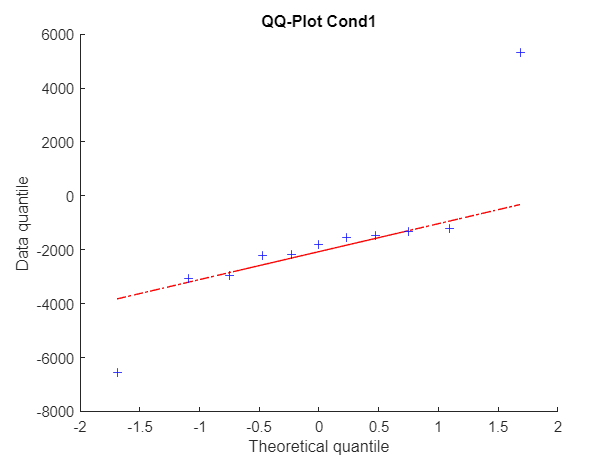

x = zeros(15, 165/15);
x(1, :) = Y(1, 1:11);
x(2, :) = Y(1, 12:22);
x(3, :) = Y(1, 23:33);
x(4, :) = Y(1, 34:44);
x(5, :) = Y(1, 45:55);
x(6, :) = Y(1, 56:66);
x(7, :) = Y(1, 67:77);
x(8, :) = Y(1, 78:88);
x(9, :) = Y(1, 89:99);
x(10, :) = Y(1, 100:110);
x(11, :) = Y(1, 111:121);
x(12, :) = Y(1, 122:132);
x(13, :) = Y(1, 133:143);
x(14, :) = Y(1, 144:154);
x(15, :) = Y(1, 155:165);
 
x1 = x(1, :);
qqplot(x1);
hold on
title('QQ-Plot Cond1');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

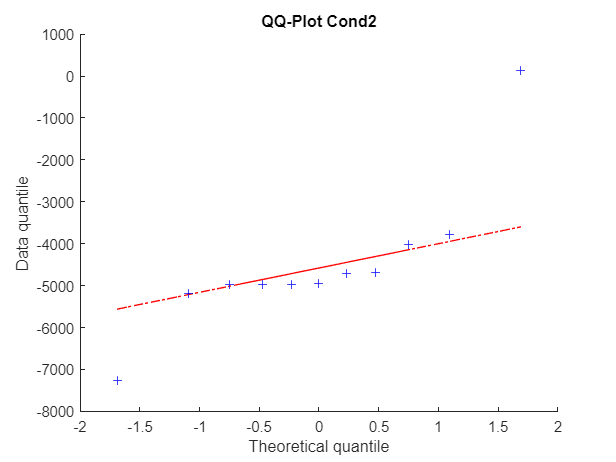


x2 = x(2, :);
qqplot(x2);
hold on
title('QQ-Plot Cond2');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

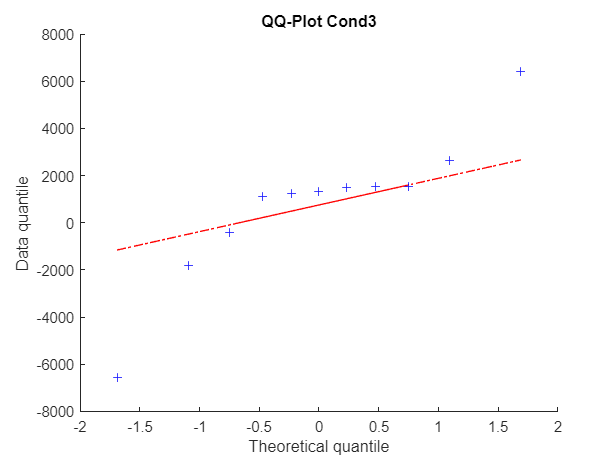


x3 = x(3, :);                               
qqplot(x3);
hold on
title('QQ-Plot Cond3');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

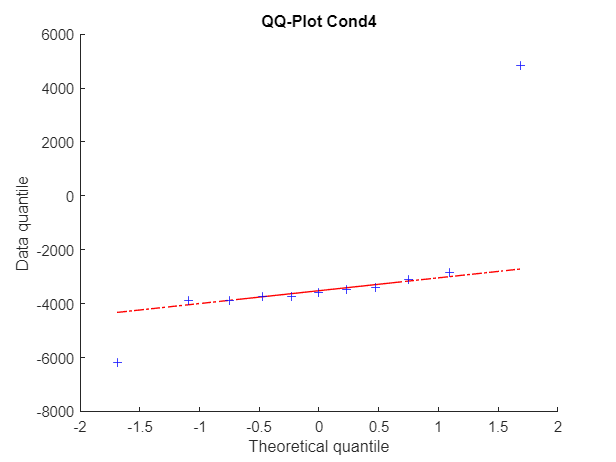


x4 = x(4, :);
qqplot(x4);
hold on
title('QQ-Plot Cond4');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

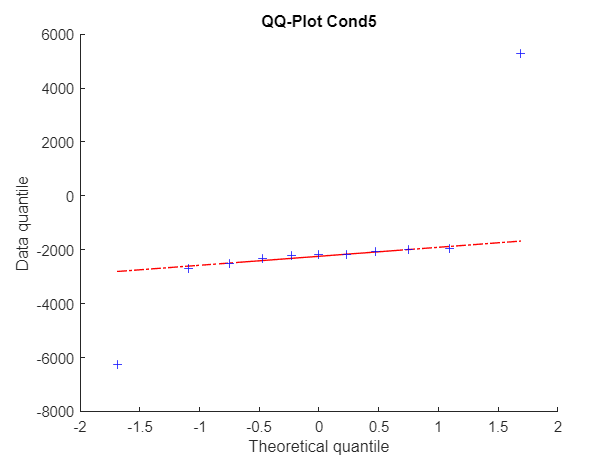


x5 = x(5, :);
qqplot(x5);
hold on
title('QQ-Plot Cond5');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

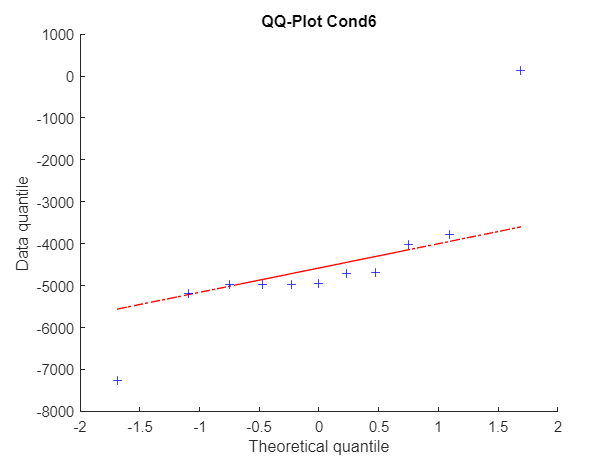


x6 = x(6, :);
qqplot(x2);
hold on
title('QQ-Plot Cond6');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

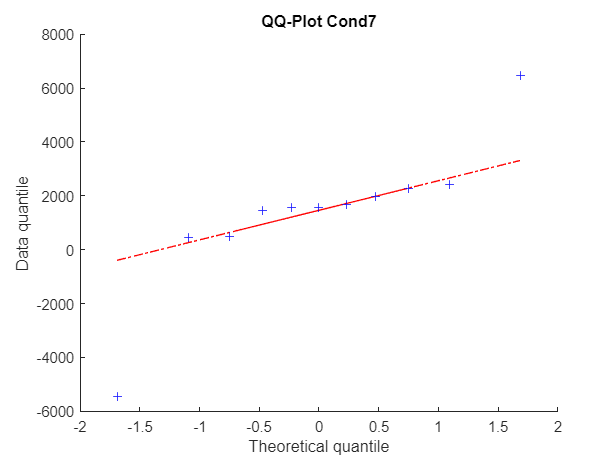


x7 = x(7, :);
qqplot(x7);
hold on
title('QQ-Plot Cond7');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

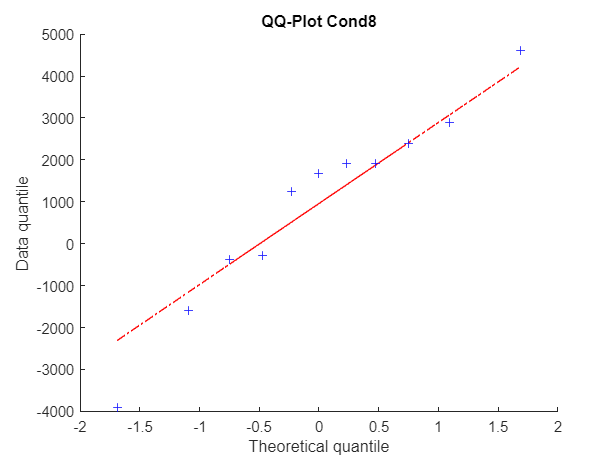

    
x8 = x(8, :);                               
qqplot(x8);
hold on
title('QQ-Plot Cond8');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

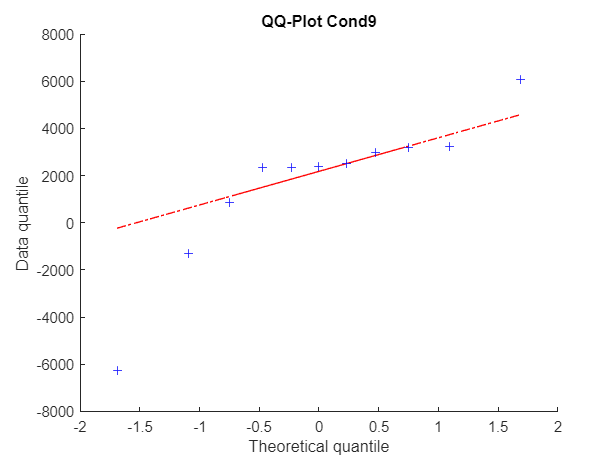


x9 = x(9, :);
qqplot(x9);
hold on
title('QQ-Plot Cond9');
xlabel('Theoretical quantile');             
ylabel('Data quantile');
hold off

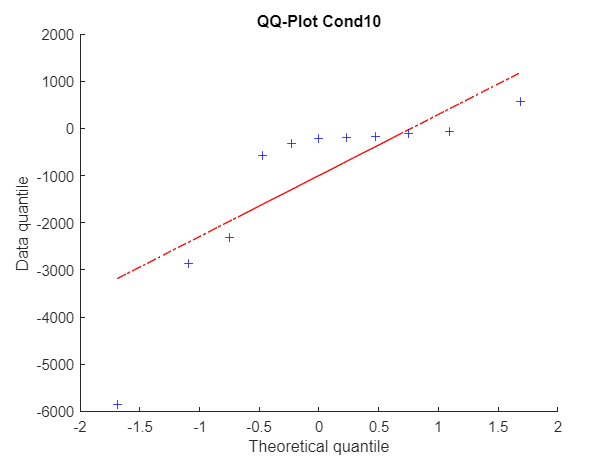


x10 = x(10, :);
qqplot(x10);
hold on
title('QQ-Plot Cond10');                    
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off

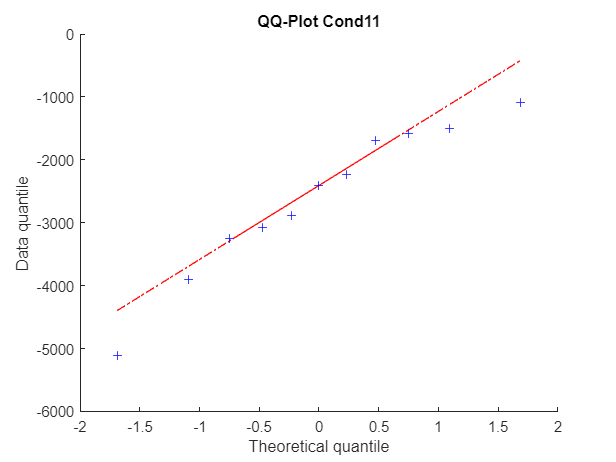


x11 = x(11, :);
qqplot(x11);
hold on
title('QQ-Plot Cond11');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off


% A partir de la tabla como n = 15 y alpha = 0.05 el threshold es 0.9503
correlation = corrcoef(x)

correlation =     1.0000    0.9201    0.8853    0.9344    0.8974    0.8768    0.7366    0.8649    0.9038    0.8400    0.8499
    0.9201    1.0000    0.9299    0.8912    0.9314    0.9289    0.7386    0.9171    0.9248    0.8877    0.9124
    0.8853    0.9299    1.0000    0.8138    0.9647    0.9733    0.7026    0.9828    0.9789    0.9500    0.9719
    0.9344    0.8912    0.8138    1.0000    0.8191    0.7850    0.6024    0.7836    0.8071    0.7374    0.7767
    0.8974    0.9314    0.9647    0.8191    1.0000    0.9830    0.7286    0.9457    0.9728    0.9624    0.9705
    0.8768    0.9289    0.9733    0.7850    0.9830    1.0000    0.7451    0.9544    0.9744    0.9548    0.9531
    0.7366    0.7386    0.7026    0.6024    0.7286    0.7451    1.0000    0.7119    0.6729    0.7411    0.6721
    0.8649    0.9171    0.9828    0.7836    0.9457    0.9544    0.7119    1.0000    0.9549    0.9735    0.9774
    0.9038    0.9248    0.9789    0.8071    0.9728    0.9744    0.6729    0.9549    1.0000    0.93

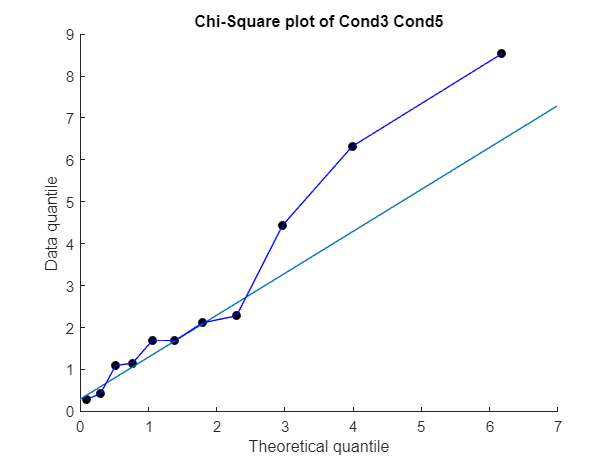


%A partir de los QQ-Plots anteriores y los coeficientes de correlación
%vemos que de los únicos que hay una probabilidad de no rechazar normalidad
%son las siguientes relaciones:
%3-5, 3-6, 3-8, 3-9, 5-9, 5-10, 5-11, 6-8, 6-9, 6-10, 6-11, 8-9, 8-10,
%8-11, 9-10, 10-11

x3x5 = x(3:5, :)';
n_pairs = length(x3x5);
q_chi = chi2inv([0.5:n_pairs-0.5]/n_pairs, 2);

mean1 = mean(x3x5);
cov1 = cov(x3x5);
d_x3x5 = diag((x3x5-mean1)*inv(cov1)*transpose(x3x5-mean1)); 
scatter(q_chi, sort(d_x3x5), '', 'black');
refline(1, min(d_x3x5));            %LÍNEA 45º
hold on
title('Chi-Square plot of Cond3 Cond5');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x3x5), 'b');
hold off

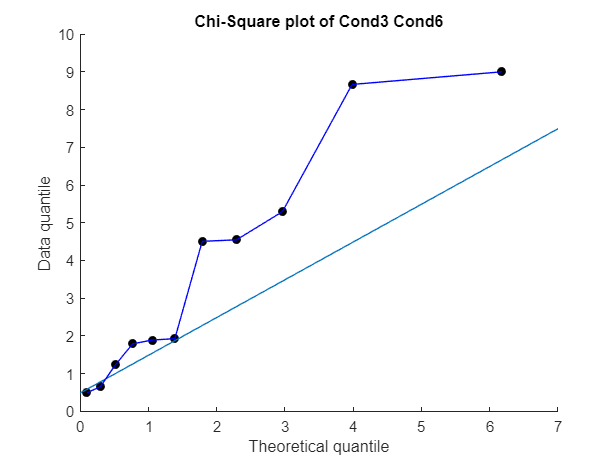


x3x6 = x(3:6, :)';
mean2 = mean(x3x6);
cov2 = cov(x3x6);
d_x3x6 = diag((x3x6-mean2)*inv(cov2)*transpose(x3x6-mean2)); 
scatter(q_chi, sort(d_x3x6), '', 'black');
refline(1, min(d_x3x6));            %LÍNEA 45º
hold on
title('Chi-Square plot of Cond3 Cond6');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x3x6), 'b');
hold off

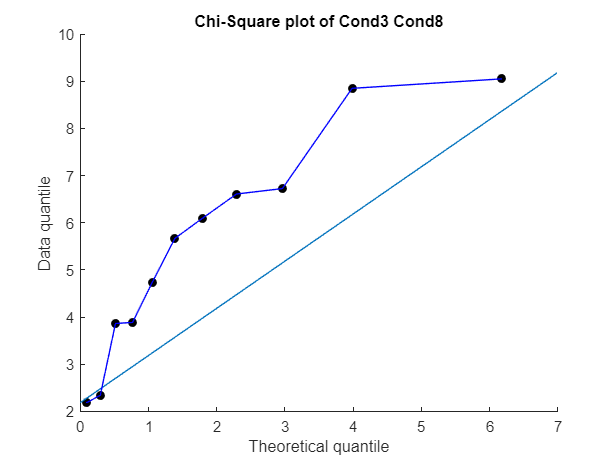


x3x8 = x(3:8, :)';
mean3 = mean(x3x8);
cov3 = cov(x3x8);
d_x3x8 = diag((x3x8-mean3)*inv(cov3)*transpose(x3x8-mean3)); 
scatter(q_chi, sort(d_x3x8), '', 'black');
refline(1, min(d_x3x8));            %LÍNEA 45º
hold on
title('Chi-Square plot of Cond3 Cond8');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x3x8), 'b');
hold off

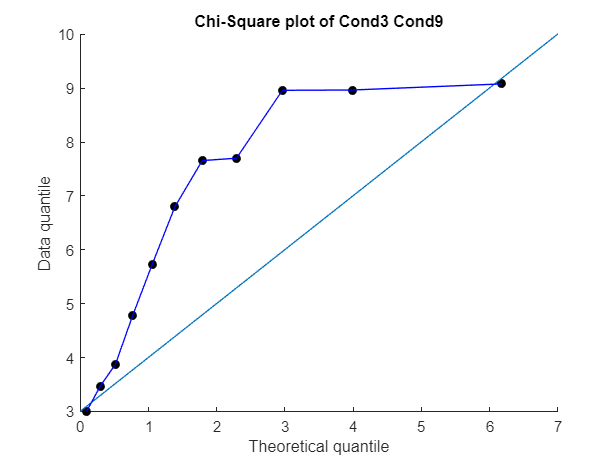


x3x9 = x(3:9, :)';
mean4 = mean(x3x9);
cov4 = cov(x3x9);
d_x3x9 = diag((x3x9-mean4)*inv(cov4)*transpose(x3x9-mean4)); 
scatter(q_chi, sort(d_x3x9), '', 'black');
refline(1, min(d_x3x9));            %LÍNEA 45º
hold on
title('Chi-Square plot of Cond3 Cond9');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x3x9), 'b');
hold off

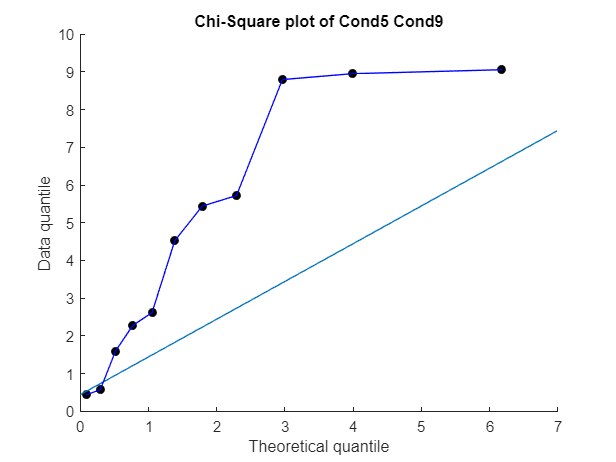


x5x9 = x(5:9, :)';
mean5 = mean(x5x9);
cov5 = cov(x5x9);
d_x5x9 = diag((x5x9-mean5)*inv(cov5)*transpose(x5x9-mean5)); 
scatter(q_chi, sort(d_x5x9), '', 'black');
refline(1, min(d_x5x9));            %LÍNEA 45º
hold on
title('Chi-Square plot of Cond5 Cond9');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x5x9), 'b');
hold off

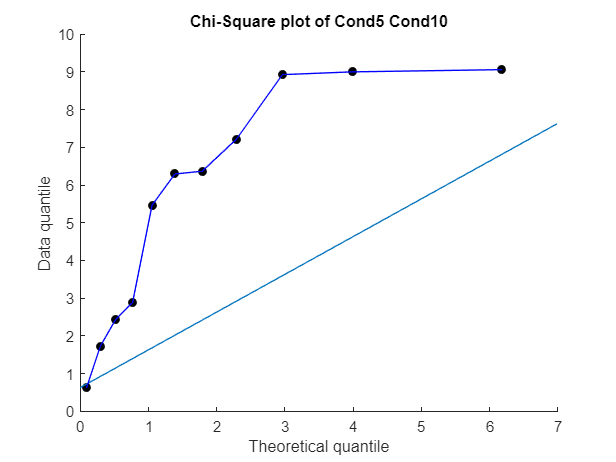


x5x10 = x(5:10, :)';
mean6 = mean(x5x10);
cov6 = cov(x5x10);
d_x5x10 = diag((x5x10-mean6)*inv(cov6)*transpose(x5x10-mean6)); 
scatter(q_chi, sort(d_x5x10), '', 'black');
refline(1, min(d_x5x10));            %LÍNEA 45º
hold on
title('Chi-Square plot of Cond5 Cond10');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x5x10), 'b');
hold off

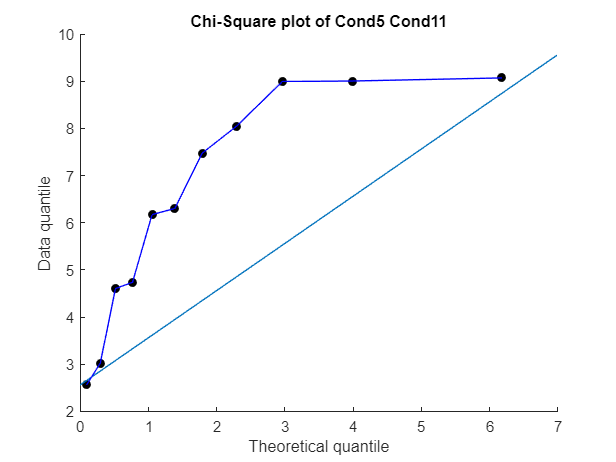


x5x11 = x(5:11, :)';
mean7 = mean(x5x11);
cov7 = cov(x5x11);
d_x5x11 = diag((x5x11-mean7)*inv(cov7)*transpose(x5x11-mean7)); 
scatter(q_chi, sort(d_x5x11), '', 'black');
refline(1, min(d_x5x11));            %LÍNEA 45º
hold on
title('Chi-Square plot of Cond5 Cond11');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x5x11), 'b');
hold off

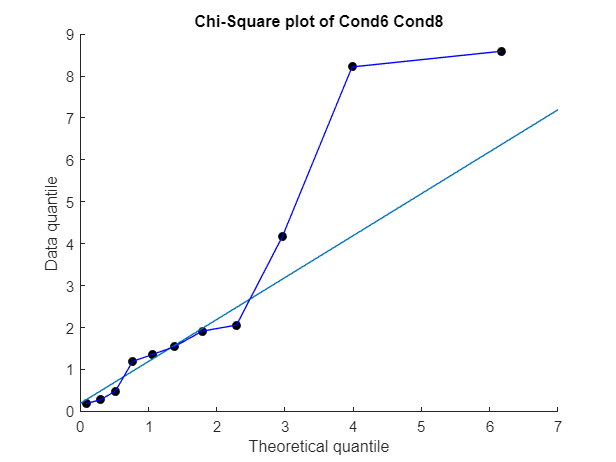


x6x8 = x(6:8, :)';
mean5 = mean(x6x8);
cov5 = cov(x6x8);
d_x6x8 = diag((x6x8-mean5)*inv(cov5)*transpose(x6x8-mean5)); 
scatter(q_chi, sort(d_x6x8), '', 'black');
refline(1, min(d_x6x8));            %LÍNEA 45º
hold on
title('Chi-Square plot of Cond6 Cond8');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x6x8), 'b');
hold off

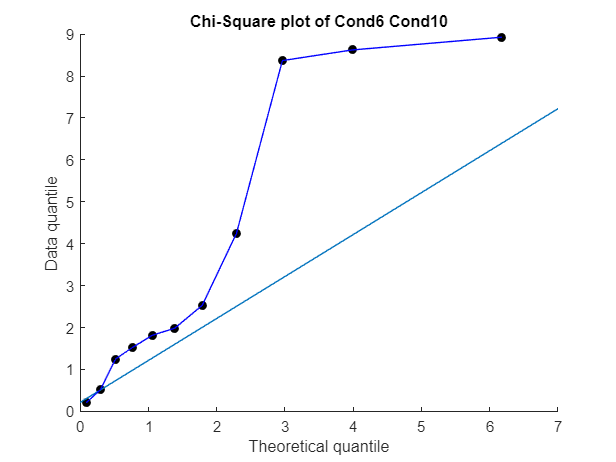


x6x9 = x(6:9, :)';
mean5 = mean(x6x9);
cov5 = cov(x6x9);
d_x6x9 = diag((x6x9-mean5)*inv(cov5)*transpose(x6x9-mean5)); 
scatter(q_chi, sort(d_x6x9), '', 'black');
refline(1, min(d_x6x9));            %LÍNEA 45º
hold on
title('Chi-Square plot of Cond6 Cond10');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x6x9), 'b');
hold off

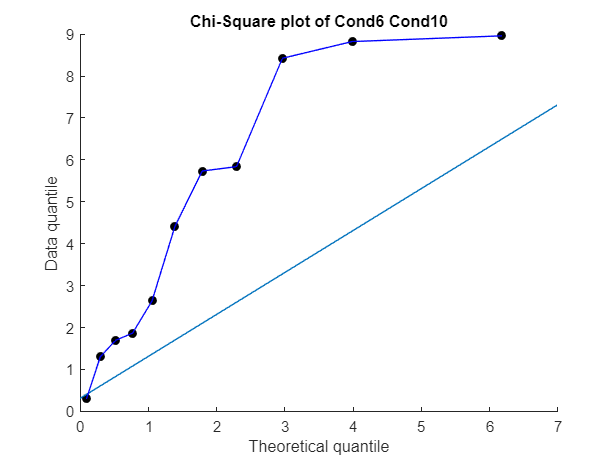


x6x10 = x(6:10, :)';
mean6 = mean(x6x10);
cov6 = cov(x6x10);
d_x6x10 = diag((x6x10-mean6)*inv(cov6)*transpose(x6x10-mean6)); 
scatter(q_chi, sort(d_x6x10), '', 'black');
refline(1, min(d_x6x10));            %LÍNEA 45º
hold on
title('Chi-Square plot of Cond6 Cond10');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x6x10), 'b');
hold off

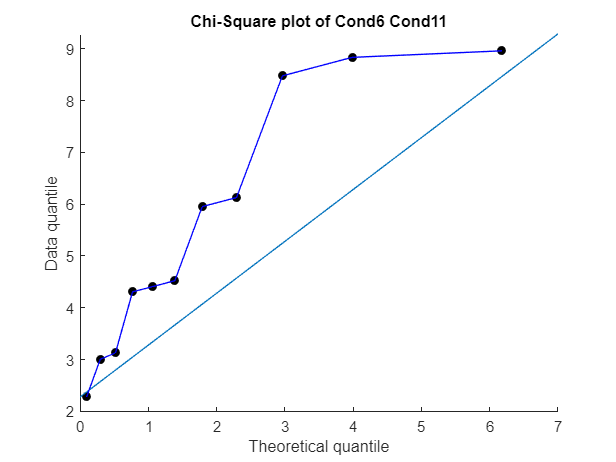


x6x11 = x(6:11, :)';
mean7 = mean(x6x11);
cov7 = cov(x6x11);
d_x6x11 = diag((x6x11-mean7)*inv(cov7)*transpose(x6x11-mean7)); 
scatter(q_chi, sort(d_x6x11), '', 'black');
refline(1, min(d_x6x11));            %LÍNEA 45º
hold on
title('Chi-Square plot of Cond6 Cond11');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x6x11), 'b');
hold off

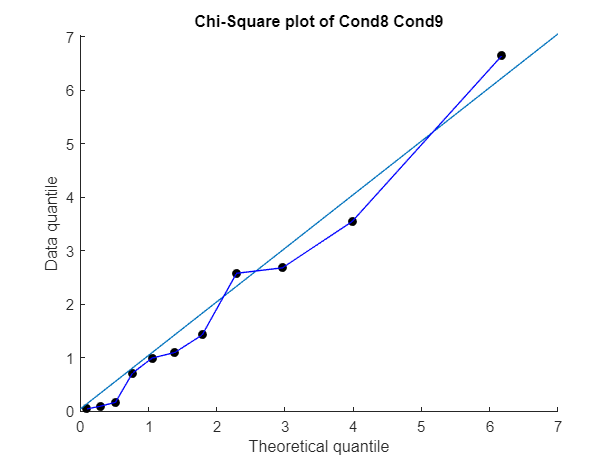


x8x9 = x(8:9, :)';
mean5 = mean(x8x9);
cov5 = cov(x8x9);
d_x8x9 = diag((x8x9-mean5)*inv(cov5)*transpose(x8x9-mean5)); 
scatter(q_chi, sort(d_x8x9), '', 'black');
refline(1, min(d_x8x9));            %LÍNEA 45º
hold on
title('Chi-Square plot of Cond8 Cond9');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x8x9), 'b');
hold off

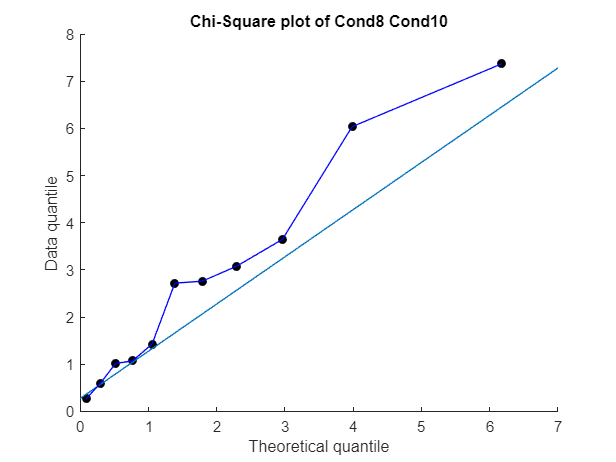


x8x10 = x(8:10, :)';
mean6 = mean(x8x10);
cov6 = cov(x8x10);
d_x8x10 = diag((x8x10-mean6)*inv(cov6)*transpose(x8x10-mean6)); 
scatter(q_chi, sort(d_x8x10), '', 'black');
refline(1, min(d_x8x10));            %LÍNEA 45º
hold on
title('Chi-Square plot of Cond8 Cond10');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x8x10), 'b');
hold off

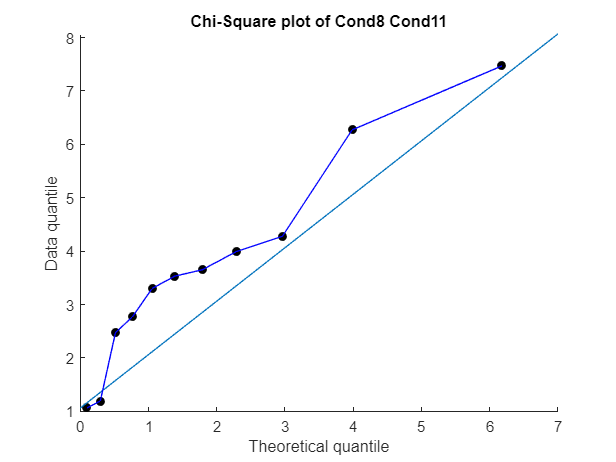


x8x11 = x(8:11, :)';
mean7 = mean(x8x11);
cov7 = cov(x8x11);
d_x8x11 = diag((x8x11-mean7)*inv(cov7)*transpose(x8x11-mean7)); 
scatter(q_chi, sort(d_x8x11), '', 'black');
refline(1, min(d_x8x11));            %LÍNEA 45º
hold on
title('Chi-Square plot of Cond8 Cond11');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x8x11), 'b');
hold off

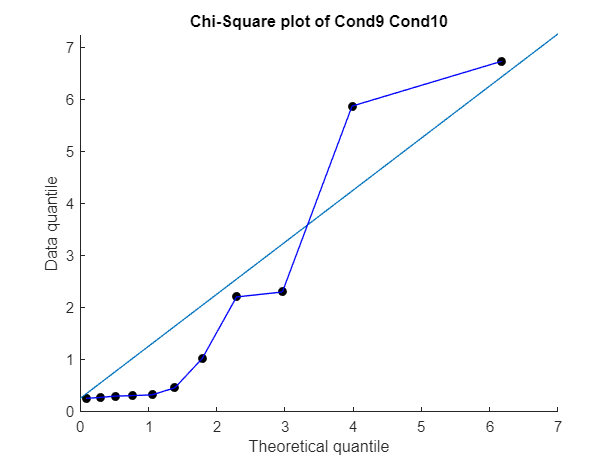


x9x10 = x(9:10, :)';
mean6 = mean(x9x10);
cov6 = cov(x9x10);
d_x9x10 = diag((x9x10-mean6)*inv(cov6)*transpose(x9x10-mean6)); 
scatter(q_chi, sort(d_x9x10), '', 'black');
refline(1, min(d_x9x10));            %LÍNEA 45º
hold on
title('Chi-Square plot of Cond9 Cond10');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x9x10), 'b');
hold off

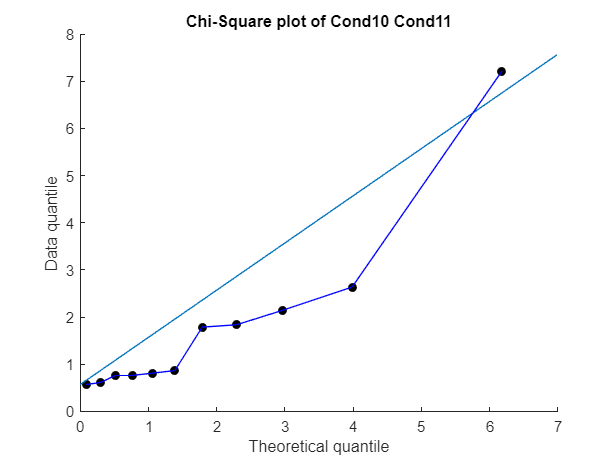


x10x11 = x(10:11, :)';
mean7 = mean(x10x11);
cov7 = cov(x10x11);
d_x10x11 = diag((x10x11-mean7)*inv(cov7)*transpose(x10x11-mean7)); 
scatter(q_chi, sort(d_x10x11), '', 'black');
refline(1, min(d_x10x11));            %LÍNEA 45º
hold on
title('Chi-Square plot of Cond10 Cond11');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
plot(q_chi, sort(d_x10x11), 'b');
hold off

A partir de los Chi-square plots anteriores vemos que podemos rechazar que las 11 condiciones siguen una distribución Normal. Es decir, en esta dimensión las 11 dimensiones no son Gausianas. Para ello usaremos bootstrap con dicho método para estimar la distribución. El método lo hemos aplicado en el partado d).

**d) Perform the test selected in (c) at significance level **$\alpha =0\ldotp 05$**. Clearly indicate your conclusion and your answer to the research question.**

n = 15;
g = 11;
B = 1e3;
theta_rep= zeros(1, B);
rng(0);
alpha = 0.05;
for j=1:B
    rs_indx = ceil(n*rand(1,n));
    X_boot = x(rs_indx, :);
    mean_x = mean(X_boot);
    S = cov(X_boot);
    %Usar Hotelling's T2
    estimator = n * (mean_x) * S^(-1) * (mean_x)';
    if estimator < 0
        j = j - 1;
    else
        theta_rep(j) = estimator;
    end
end
theta_rep

theta_rep = 	1.0e+19 *

         0    0.0128         0    0.0000         0    0.0002         0    0.0002         0    0.0013    0.0003    0.0011    0.0001         0    0.0644    0.0091         0    0.0009    0.0400    0.0035    0.0036         0    0.0013    0.7904         0         0    0.0049         0         0         0    0.0008    0.0007         0    0.0005         0         0         0         0    0.0002    0.0256    0.0059         0         0         0    0.0003    0.0008         0    0.0014         0    0.0039


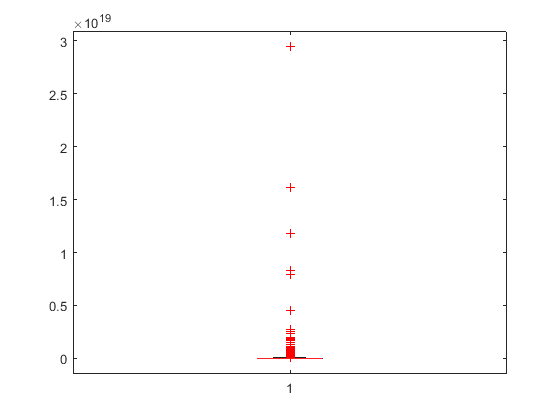

boxplot(theta_rep)


%Usar Hotteling's T2
X_original = x;
mean_x = mean(X_original);
S = cov(X_original);
%Usar Hotelling's T2
estimator = n * mean_x * (S)^(-1) * mean_x';

theta_hat = estimator;
n_against_h0 = length(find(theta_rep >= theta_hat));
p_value = (n_against_h0+1)/(B+1)

p_value = 0.5415

Como el p_value es mayor a alpha, rechazamos la hipotesis nula, y lo por lo tanto rechazamos el hecho de que las imagenes de las 11 condiciones difieran significativamente.

**PROBLEM 3**

**a) State the null and alternative hypotheses for the research question indicated above.**

Hipótesis:


$$\begin{array}{l}
H_0 :\mu_1 =\mu_2 =\ldotp \ldotp \ldotp =\mu_k \Rightarrow \delta =0\\
H_A :\mu_l \not= \mu_2 \;\textrm{for}\;\textrm{at}\;\textrm{least}\;\textrm{two}\;l\not= l^{\prime } 
\end{array}$$


donde $\mu$ es la media de la población y k el número de grupos relacionados. En este caso k = 3.

**b) Apply Kernel-PCA to reduce the dimensionality of your input data and display the first 2 resulting components. ****Hint****: the following kernel function is a reasonable choice for this dataset:    **


$$k\left(x_i ,x_j \right)=\exp \left(-\gamma ||x_i -x_j ||\right)$$


**for some **$\gamma >0$. **The value of **$\gamma$ **can be tuned by visual inspection of the result (e.g. displaying the first two components). It is also possible to use a different kernel of your choice.**

X = SM22Lab6AbstractData{:,:};
n = size(X, 2);
count_1 = 0;
count_2 = 0;
count_3 = 0;
for i = 1:n
    if X(1,i) == 1
        count_1 = count_1 + 1;
    elseif X(1, i) == 2
       count_2 = count_2 + 1;
    else
        count_3 = count_3 + 1;
    end
end
p = size(X, 1) - 1;
x1 = zeros(p, count_1);
j = 1;
x2 = zeros(p, count_2);
l = 1;
x3 = zeros(p, count_3);
k = 1;
for i = 1:n
    if X(1,i) == 1
        x1(:, j) = X(2:(p+1), i)';
        j = j + 1;
    elseif X(1, i) == 2
       x2(:, l) = X(2:(p+1), i)';
        l = l + 1;
    else
        x3(:, k) = X(2:(p+1), i)';
        k = k + 1;
    end
end
X = [x1 x2 x3]

X =     0.2620   -0.0566    0.0082    0.0032    0.0051   -0.0060    0.0206   -0.0250    0.0199   -0.0035   -0.0644    0.0511   -0.0122   -0.0298    0.0256   -0.0040   -0.0293   -0.0099   -0.0210    0.0201    0.0165    0.0622    0.0476   -0.0343   -0.0966    0.0292    0.0820   -0.0132    0.0412   -0.0339    0.0990    0.0520   -0.0002    0.0091   -0.1201   -0.0116    0.0063    0.0084    0.0038   -0.0324    0.0066    0.0523    0.0927   -0.0292    0.0051    0.0593   -0.0710    0.0139   -0.0074    0.0829
   -0.0045    0.6192    0.0993    0.0099   -0.0366    0.0933    0.0074    0.0121   -0.0306   -0.0077    0.0234   -0.0513   -0.0013   -0.0212    0.0648   -0.0389   -0.0045    0.0605    0.0072   -0.0152   -0.0028    0.0407   -0.0214    0.0115   -0.0104   -0.0497   -0.0384    0.0163    0.0397    0.0097    0.0850    0.0083   -0.0121    0.0065    0.0020    0.0592   -0.0381    0.2502   -0.0106    0.0028    0.0065    0.0116   -0.0097   -0.0183   -0.0142   -0.0237    0.0190    0.0115    0.0145    0

K = zeros(n);
for i = 1:n
    for j = 1:n
        K(i, j)= exp(-13*norm(X(:,i)-X(:,j)));
    end
end
[V, D] = eig(K);
[sorted_D, sorted_indx] = sort(diag(D), 'desc');
sorted_V = V(:, sorted_indx);
sorted_D = diag(sorted_D);
Y =  sorted_V' * (K - mean(K))';
Y_2pc = Y(1:2, :)

Y_2pc =    -2.4361   -2.7772   -2.7485    0.9561   -1.1245   -2.7158   -0.3106   -2.0039   -2.5666    0.5078    0.3221   -2.3497    0.4632    0.1901   -2.7715   -2.7187    0.2239   -1.8217    1.2909   -1.1207    1.7643   -0.3870   -2.1700   -0.3236   -0.5190   -1.9041   -0.7671   -0.2180   -2.3917    0.9835   -2.5068   -1.6757   -1.6946    1.2168   -1.7691    0.2214    0.1819   -2.7444    1.5868    0.4641   -1.9002   -1.6192   -2.3985   -1.0701    1.3644   -2.1435    0.2614   -1.1382   -1.1507   -2.5075
   -0.0115    0.0444    0.0421   -1.2656   -1.1197    0.0409   -1.3946   -0.7380   -0.2624   -1.3180   -0.4671    0.4182   -0.9362   -0.6767    0.0448   -0.0462   -0.7292   -0.8655   -1.0597   -1.2830   -0.7683   -0.7248   -0.6656   -1.2946    0.2459   -0.0151   -0.7831   -1.5444    0.3610   -0.8114    0.1537   -0.9616   -1.1201   -0.6162   -0.5608   -0.4171   -1.0701    0.0428   -1.0001   -1.1531   -0.4577   -0.1550    0.1654    0.8354   -0.9835    0.5274   -0.3241   -1.3272   -1.4241 

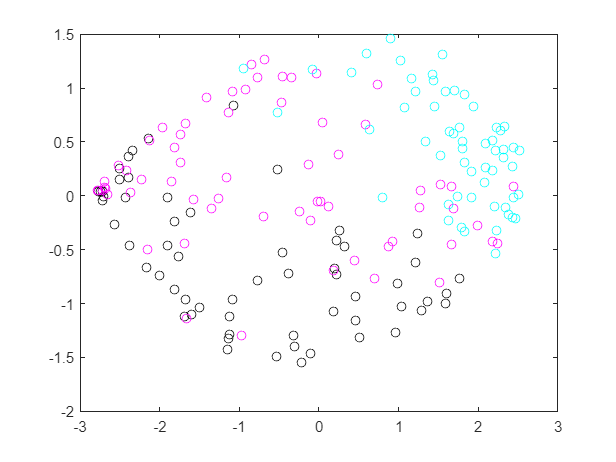


plot(Y_2pc(1, 1:count_1), Y_2pc(2, 1:count_1), 'o', 'Color', 'black');
hold on
plot(Y_2pc(1, count_1+1:count_1+count_2), Y_2pc(2, count_1+1:count_1+count_2), 'o', 'Color', 'magenta');
plot(Y_2pc(1, count_1+count_2+1:count_1+count_2+count_3), Y_2pc(2, count_1+count_2+1:count_1+count_2+count_3), 'o', 'Color', 'cyan');
hold off

**c) Indicate what method would you use to test the hypotheses stated in (a) using the 2-dimensional representation obtained in (b). Verify that your data fulfills the assumptions required by the method to make sure that the result of the analysis will be valid, using significance level **$\alpha =0\ldotp 01$.

El modelo que nosotros proponemos es MANOVA, las asunciones son:

    1- Each sample $\overrightarrow{X_{l1} } ,\ldotp \ldotp \ldotp ,\overrightarrow{X_{ln_l } }$ for $1\le l\le g$ comes from a normal distribution with $\overrightarrow{\mu_p }$ and $\Sigma_p$.

    2- The random samples for each population are independent of each other.

    3- All populations have the same covariance matrix. 

Asumimos que todas tres asunciones se cumplen. En este caso g=3, ya que tenemos 3 grupos (fabricantes).

Y_2 = Y_2pc;

x1 = Y_2pc(:, 1:count_1);
x2 = Y_2pc(:, count_1+1:count_1+count_2);
x3 = Y_2pc(:, count_1+count_2+1:count_1+count_2+count_3);


% A partir de la tabla como n = 62 y alpha = 0.05 el threshold es 0.9811
x = [x1 x2 x3]

x =    -2.4361   -2.7772   -2.7485    0.9561   -1.1245   -2.7158   -0.3106   -2.0039   -2.5666    0.5078    0.3221   -2.3497    0.4632    0.1901   -2.7715   -2.7187    0.2239   -1.8217    1.2909   -1.1207    1.7643   -0.3870   -2.1700   -0.3236   -0.5190   -1.9041   -0.7671   -0.2180   -2.3917    0.9835   -2.5068   -1.6757   -1.6946    1.2168   -1.7691    0.2214    0.1819   -2.7444    1.5868    0.4641   -1.9002   -1.6192   -2.3985   -1.0701    1.3644   -2.1435    0.2614   -1.1382   -1.1507   -2.5075
   -0.0115    0.0444    0.0421   -1.2656   -1.1197    0.0409   -1.3946   -0.7380   -0.2624   -1.3180   -0.4671    0.4182   -0.9362   -0.6767    0.0448   -0.0462   -0.7292   -0.8655   -1.0597   -1.2830   -0.7683   -0.7248   -0.6656   -1.2946    0.2459   -0.0151   -0.7831   -1.5444    0.3610   -0.8114    0.1537   -0.9616   -1.1201   -0.6162   -0.5608   -0.4171   -1.0701    0.0428   -1.0001   -1.1531   -0.4577   -0.1550    0.1654    0.8354   -0.9835    0.5274   -0.3241   -1.3272   -1.4241    0

correlation = corrcoef(x')

correlation =     1.0000    0.1029
    0.1029    1.0000


Viendo la matriz de correlación, no rechazamos que nuestros datos vienen de una distribución normal.

**d) Perform the test selected in (c) at significance level **$\alpha =0\ldotp 01$**. Clearly indicate your conclusion and your answer to the research question.**


n_1 = size(x1, 2);
n_2 = n_1;
n_3 = n_1;

mean_1 = mean(x1, 2);
mean_2 = mean(x2, 2);
mean_3 = mean(x3, 2);
mean_x = mean(Y_2, 2);

tau_1 = mean_1-mean_x;
tau_2 = mean_2-mean_x;
tau_3 = mean_3-mean_x;

error_1 = x1 - mean_1;
error_2 = x2 - mean_2;
error_3 = x3 - mean_3;

g = 3;
B = n_1 * ((tau_1)*transpose(tau_1)) + n_2 * ((tau_2)*transpose(tau_2)) + n_3 * ((tau_3)*transpose(tau_3));
dfB = g-1;
W = error_1*transpose(error_1) + error_2*transpose(error_2) + error_3*transpose(error_3);
dfW = n_1 + n_2 + n_3 - g;
p = size(x1, 1);

estimator = det(W)/(det(W+B));
s = min(p, dfB);
df1 = p * dfB;
df2 = s * (dfW - (p - dfB + 1) / 2)-((p * dfB - 2) / 2);
estimator_f = ((1-estimator^(1/s))/df1)/((estimator^(1/s))/df2)

estimator_f = 80.1453


alpha = 0.01;
crit = finv(1-alpha,df1,df2)

crit = 3.3711


if (estimator_f > crit)
    disp("We reject the null hypothesis at significance level 0.01.");
else 
    disp("We cannot reject the null hypothesis at significance level 0.01.");
end

We reject the null hypothesis at significance level 0.01.


Al ser el estimador mayor al valor critico rechazamos la hipotesis nula. Por lo tanto, rechazamos el hecho de que los productos de los 3 fabricantes no difieren significativamente.